# Zero-forcing Beamformer Implementation and Comparison

## Parameters

M = 3;                  % no. of antennas
N = 20;                 % no. of samples
Delta = 1/2;            % spacing b/w antennas (in terms of wavelength)
theta = [-20, 30];      % directions of sources (in degrees) (-90 to 90)
f = [0.1, 0.12];        % normalized frequency (b/w 0 and 1)
d = length(theta);      % no. of sources
SNR = 10;               % in dB

### Data generation

[X, A, S] = gendata(M, N, Delta, theta, f, SNR);

## ESPRIT for direction, frequency estimation

theta_est = esprit(X, d);
fprintf('True angles: %s degrees\n', mat2str(theta, 4));

True angles: [-20 30] degrees


fprintf('Estimated angles: %s degrees\n', mat2str(theta_est', 4));

Estimated angles: [-20.26 30.49] degrees



f_est = espritfreq(X, d);
fprintf('True frequencies: %s\n', mat2str(f, 4));

True frequencies: [0.1 0.12]


fprintf('Estimated frequencies: %s\n', mat2str(f_est', 4));

Estimated frequencies: [0.1081 0.1141]


## Functions to create vectors

### a) For a given angle - steering vector

steering_vector = @(angle_deg, M, Delta) exp(-1j * 2 * pi * Delta * (0:M-1)' * sind(angle_deg));

### b) For a given frequency - temporal signature vector

temporal_vector = @(freq, N) exp(1j * 2 * pi * freq * (0:N-1));

## Estimated matrices for zero-forcing

### a) Based on DoA - estimated steering matrix

A_est_doa = zeros(M, d);
for i = 1:d
    A_est_doa(:, i) = steering_vector(theta_est(i), M, Delta);
end

### b) Based on frequency - estimated temporal signature matrix

S_est_freq = zeros(d, N);
for i = 1:d
    S_est_freq(i, :) = temporal_vector(f_est(i), N);
end

## Zero-forcing beamformers

W_doa = A_est_doa * pinv(A_est_doa' * A_est_doa) * A_est_doa' % projection matrix

W_doa =    0.5470 - 0.0000i   0.1997 + 0.0517i  -0.3962 - 0.2197i
   0.1997 - 0.0517i   0.9060 + 0.0000i   0.1997 + 0.0517i
  -0.3962 + 0.2197i   0.1997 - 0.0517i   0.5470 - 0.0000i


W_freq = S_est_freq' * pinv(S_est_freq * S_est_freq') * S_est_freq % projection matrix

W_freq =    0.1842 + 0.0000i   0.1304 + 0.1095i   0.0271 + 0.1539i  -0.0711 + 0.1231i  -0.1204 + 0.0438i  -0.1070 - 0.0390i  -0.0498 - 0.0864i   0.0149 - 0.0842i   0.0546 - 0.0458i   0.0569 + 0.0000i   0.0326 + 0.0274i   0.0049 + 0.0279i  -0.0070 + 0.0121i   0.0003 - 0.0001i   0.0138 + 0.0050i   0.0145 + 0.0252i  -0.0076 + 0.0427i  -0.0442 + 0.0370i  -0.0720 - 0.0001i  -0.0660 - 0.0555i
   0.1304 - 0.1095i   0.1578 + 0.0000i   0.1113 + 0.0934i   0.0230 + 0.1307i  -0.0600 + 0.1040i  -0.1009 + 0.0367i  -0.0889 - 0.0324i  -0.0409 - 0.0710i   0.0120 - 0.0681i   0.0432 - 0.0362i   0.0435 + 0.0000i   0.0235 + 0.0198i   0.0031 + 0.0176i  -0.0025 + 0.0043i   0.0074 - 0.0027i   0.0194 + 0.0071i   0.0167 + 0.0291i  -0.0081 + 0.0456i  -0.0454 + 0.0380i  -0.0720 - 0.0001i
   0.0271 - 0.1539i   0.1113 - 0.0934i   0.1342 - 0.0000i   0.0943 + 0.0791i   0.0194 + 0.1103i  -0.0504 + 0.0873i  -0.0842 + 0.0306i  -0.0736 - 0.0268i  -0.0335 - 0.0581i   0.0097 - 0.0549i   0.0340 - 0.0285i   0.0331 + 0.0000i 

### Applying to noiseless data for verification

X_noiseless = A * S;
Y_doa = W_doa * X_noiseless;
Y_freq = X_noiseless * W_freq;

% verifying recovery
fprintf('DOA beamformer MSE: %e\n', mean(abs(Y_doa(:) - X_noiseless(:)).^2));

DOA beamformer MSE: 4.480603e-04


fprintf('Frequency beamformer MSE: %e\n', mean(abs(Y_freq(:) - X_noiseless(:)).^2));

Frequency beamformer MSE: 5.763351e-03


## Spatial responses

theta_grid = -90:0.5:90;
freq_grid = 0:0.05:1;
response_doa = zeros(length(theta_grid), d);
response_freq = zeros(length(freq_grid), d);

### Spatial responses for DoA-based beamformer

for i = 1:d
    w_doa_i = A_est_doa(:, i);
    for j = 1:length(theta_grid)
        a_theta = steering_vector(theta_grid(j), M, Delta);
        response_doa(j, i) = abs(w_doa_i' * a_theta);
    end
end

### Spatial responses for frequency-based beamformer

for i = 1:d
    w_freq_i = S_est_freq(i, :);
    for j = 1:length(freq_grid)
        a_freq = temporal_vector(freq_grid(j), N);
        response_freq(j, i) = abs(a_freq * w_freq_i');
    end
end

### Plotting

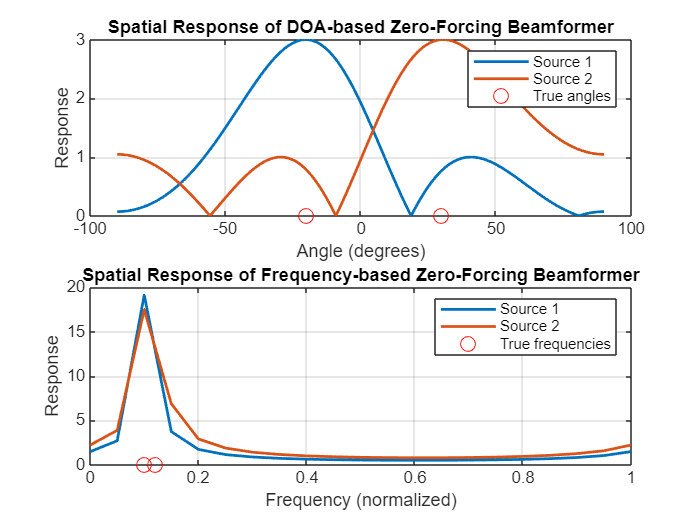

figure(1);

subplot(2, 1, 1);
plot(theta_grid, response_doa, 'LineWidth', 1.5);
grid on;
title('Spatial Response of DOA-based Zero-Forcing Beamformer');
xlabel('Angle (degrees)');
ylabel('Response');
hold on;
plot(theta, zeros(size(theta)), 'ro', 'MarkerSize', 8);
legend('Source 1', 'Source 2', 'True angles');
hold off;

subplot(2, 1, 2);
plot(freq_grid, response_freq, 'LineWidth', 1.5);
grid on;
title('Spatial Response of Frequency-based Zero-Forcing Beamformer');
xlabel('Frequency (normalized)');
ylabel('Response');
hold on;
plot(f, zeros(size(f)), 'ro', 'MarkerSize', 8);
legend('Source 1', 'Source 2', 'True frequencies');
hold off;